ant = waveguideCircular_antennaDesigner

ant =   waveguideCircular with properties:

        Radius: 0.0400
        Height: 0.2100
    FeedHeight: 0.0300
     FeedWidth: 0.0020
    FeedOffset: 0.0703
     Conductor: [1×1 metal]
          Tilt: 0
      TiltAxis: [1 0 0]
          Load: [1×1 lumpedElement]


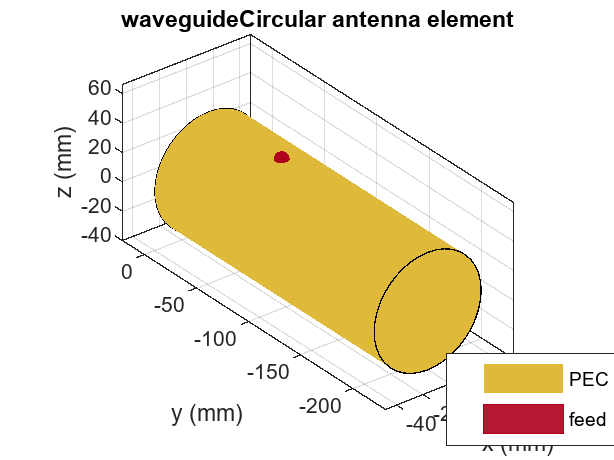

ant.Tilt = -90;
ant.TiltAxis = 'y';
show(ant)

pattern(ant,2.442e9)
%s=sparameters(ant,linspace(2.197e9,2.686e9,45));
%rfplot(s);
%figure;
%impedance(ant,linspace(2.197e9,2.686e9,45));
%patternAzimuth(ant,2.442e9)
tx = txsite('Name', 'Cantenna A', 'Antenna', ant, 'Latitude', 51.264793, 'Longitude', -1.452258,'TransmitterPower',1)

tx =   txsite with properties:

                    Name: 'Cantenna A'
        CoordinateSystem: 'geographic'
                Latitude: 51.2648
               Longitude: -1.4523
                 Antenna: [1×1 waveguideCircular]
            AntennaAngle: 0
           AntennaHeight: 10
              SystemLoss: 0
    TransmitterFrequency: 1.9000e+09
        TransmitterPower: 1


show(tx)
rx = rxsite('Name', 'Cantenna B', 'Antenna', ant, 'Latitude', 51.22881754, 'Longitude', -1.46736136)
show(rx)
%tx.AntennaAngle = angle(tx, rx(1));
coverage(tx,'rain','SignalStrengths',-80)
link(rx,tx,'rain')
coverage(tx,rx)